# **drawSpiral**

Draw the Archimedean spiral

## Description

The Archimedean spiral is the curve that corresponding to the locations over time of a point moving away from a fixed point with a constant speed along a line that rotates with constant angular velocity [1]. Its equation in polar coordiantes $\left(r,\theta \right)$is


$$r=c\theta$$


where *c* is real parameter. If *a *is distance between succesive turnings and $\theta$is in degrees then the equation is


$$r=\frac{a\;\theta^0 }{360}$$


## Syntax

drawSpiral(a,sang,eang)

drawSpiral(a,sang,eang,xc,yc)

drawSpiral(a,sang,eang,xc,yc,rot)

drawSpiral(a,sang,eang,LineSpec)

drawSpiral(a,sang,eang,'-np',np)

p = drawSpiral(__)

## Description

drawSpiral(a,sang,eang) draw spiral with default number of points fix(eang-sang) and current line specification. 

drawSpiral(a,sang,eang,xc,yc) draw spiral with given center

drawSpiral(a,sang,eang,xc,yc,rot) draw spiral with given center and rotation

drawSpiral(a,sang,eang,LineSpec)  sets the line style, line width, and color.

drawSpiral(a,sang,eang,'-np',np) set the number of points on the output curve.

p = drawSpiral(__) returns structure with fields contain x-value and y-value for the curve.

## Method

For calculation of the coordinates of the curve **drawSpiral **call function **evalSpiral( xc,yc,rot,a,th)  **which returns coordinates *x *and *y *of the curve at given angles th . For usage of **evalSpiral **see Example 1.

Catenary is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**a **- distance between succesive turns 

**sang** - start angle in degrees

**eang** - end angle in degrees

### Optional arguments

**xc - **x-coordinate of the center 

**yc **- y-coordinate of the center 

**rot **- rotation angle about the center in degrees

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve ( scalar integer value > 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk,p.yk - key points: 1=start,2=end,3=center

- p.color - line color

## Examples

### Example 1

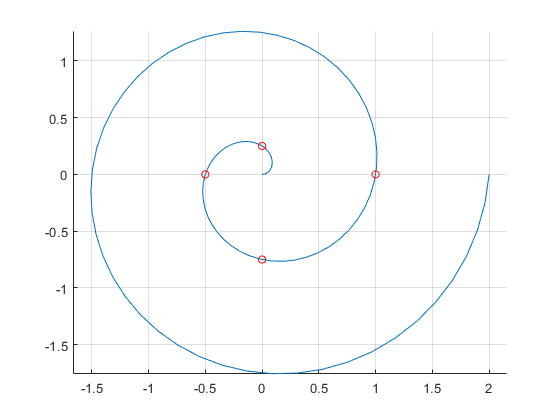

%Data 
b = 1;
sang = 0;
eang = 2*360;
figure
hold on
axis equal
[x,y] = evalSpiral(b,0,0,0,linspace(sang,eang));
plot(x,y)
[x,y] = evalSpiral(b,0,0,0,[90,180,270,360]);
scatter(x,y,30,'r')
grid on

### Example 2

%Data 
b = 1;
sang = 130;
eang = 2*360;
figure
hold on
axis equal
scatter(0,0)
p = drawSpiral(b,sang,eang)

p = struct with fields:
       xk: [-0.2321 2 0]
       yk: [0.2766 0 0]
    color: 'k'


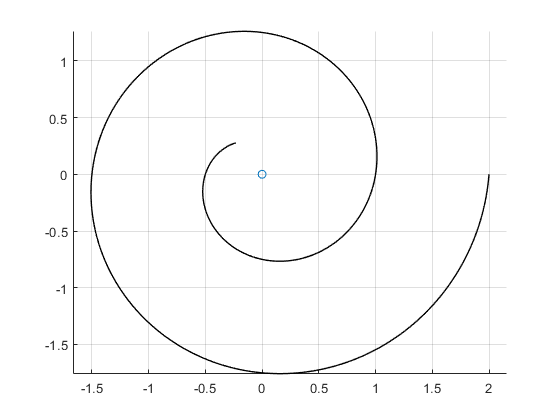

grid on

### Example 3

figure
hold on
axis equal
b = 2;
eang = 3*360; 
x0 = 1;
y0 = 2;
rot = 45;
p = drawSpiral(b,0,eang,x0,y0,rot,'-np',80)

p = struct with fields:
       xk: [1 5.2426 1]
       yk: [2 6.2426 2]
    color: 'k'


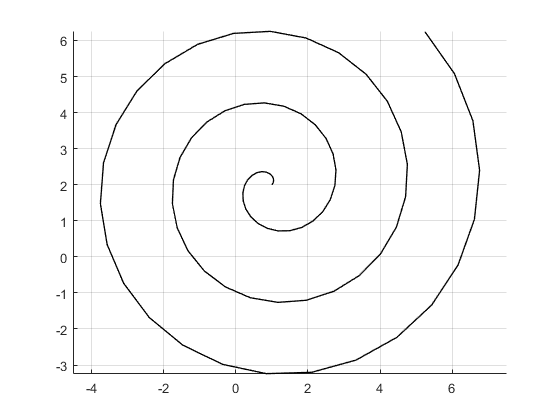

grid on

### Example 4

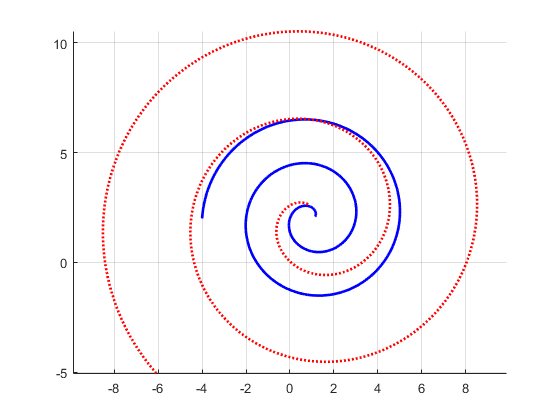

figure
hold on
axis equal
a = 2; 
b = 2;
sang = 30;
eang = 2.5*360; 
x0 = 1;
y0 = 2;
rot = 45;
drawSpiral(b,sang,eang,x0,y0,'LineWidth',2,'Color','b')
drawSpiral(2*b,2*sang,eang,x0,y0,rot,'LineWidth',2,'Color','r','LineStyle',':')
grid on

## **See Also**

## References

[1]  [WikipediA, Archimedean spiral](https://en.wikipedia.org/wiki/Archimedean_spiral)